# Mobile Networking Simulation: Mesh Network for Emergency Communications

The function of this program is to demonstrate the viability of a temporary mesh networking solution for emergency situations where normal communications methods have been disrupted. These devices would be dropped from aeroplanes flying over the affected area dropping small battery operated communications devices. These devices would connect to each other over LoRaWAN connections and also act as WiFi APs serving a web portal used to contact emergency services that can be connected to using a smartphone or other device. 

This simulation will be split into two parts, one which determines the ideal number of devices to use over a 2km area and therefore the ideal device/km^2 ratio to create a robust mesh network, and a second part which will model a simplified version of LoRa's CHIRP (Compressed High Intensity Radar Pulse) symbol generation.

## Part 1: Mesh Simulation

This part is meant to simulate and gather data on the number of devices needed for a robust mesh network in a 4km^2 area. The demonstration code below uses 90 devices with a range of 300m each. In ideal situations LoRa is able to achieve distances of >10KM, so in order to simulate smaller low power devices and less ideal conditions the range of 300m was chosen. 

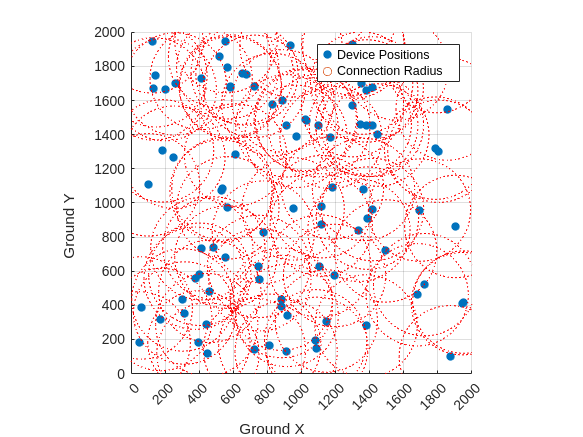

numDevices = 90; % Number of devices
deviceRange = 300; % Define device range in meters
groundWidth = 2000; % Define ground width size in meters

rng(3) % make deterministic. seed chosen to demonstrate multiple clusters of devices

% Preallocate result matrix with the correct size (20-by-2 for 20 devices)
result = zeros(numDevices, 2);

% Generate random values based on the number of devices
result(:,1) = randi([1 groundWidth], numDevices, 1); % X data
result(:,2) = randi([1 groundWidth], numDevices, 1); % Y data

% Create a scatter plot
scatter(result(:,1), result(:,2), 'filled');
xlabel('Ground X');
ylabel('Ground Y');
xticks(0:200:groundWidth)
yticks(0:200:groundWidth)
xlim([0 groundWidth])
ylim([0 groundWidth])
daspect([1 1 1])
% title(['Scatter Plot of Simulated Ground (' num2str(numDevices) ' devices)']);
grid on;

% Hold the plot to overlay the circles
hold on;
scatter([],[]) % line to make the legend functional. weird hack
% Plot thin red circles around each device
for i = 1:numDevices
    % Create a circle with a given radius and position
    rectangle('Position', [result(i,1)-deviceRange, result(i,2)-deviceRange, 2*deviceRange, 2*deviceRange], ...
              'Curvature', [1, 1], 'EdgeColor', 'r', 'EdgeColorMode', 'auto', 'LineStyle',':'); 
end
legend('Device Positions','Connection Radius')
hold off;

The above graph shows a representation of a 2km 2d ground plane with blue dots representing the positions of devices. If a blue dot is inside of another dots' range then we treat them as connected. This connection information is turned into an adjacency matrix and graph in the next code snippet.

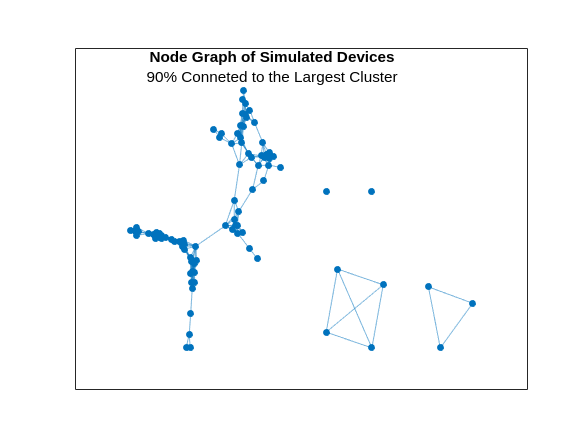


adjMatrix = zeros(numDevices, numDevices);
for i = 1:numDevices
    for j = 1:numDevices
        if (sqrt( abs(result(i,1)-result(j,1))^2 + abs(result(i,2)-result(j,2))^2) <= deviceRange) % messy pythagoras theorem
            adjMatrix(i,j) = 1;
            if (i==j)
                adjMatrix(i,j) = 0;
            end
        end
    end
end
grp = graph(adjMatrix);
% Release the hold on the plot
[bin,binsize] = conncomp(grp);
plot(grp, "NodeLabel",'')
title('Node Graph of Simulated Devices')
subtitle(num2str((binsize(1)/numDevices)*100) + "% Conneted to the Largest Cluster")

This graph is a logical representation of the devices in the previous graph. It allows us to visualise the disconnected clusters. Here we can see the large main cluster next to two smaller clusters and two individual devices not within the main network. Ideally all devices would be connected to each other, but some percentage of disconnected devices is likely inevitable.

The code above has been converted into a class so it can be easily run multiple times with a different seed. This allows us to run the simulation multiple times in different randomised scenarios. The simulation will be run for different numbers of devices ranging from 50-120. We will run the simulation 1000 times and average the results for more accurate data.

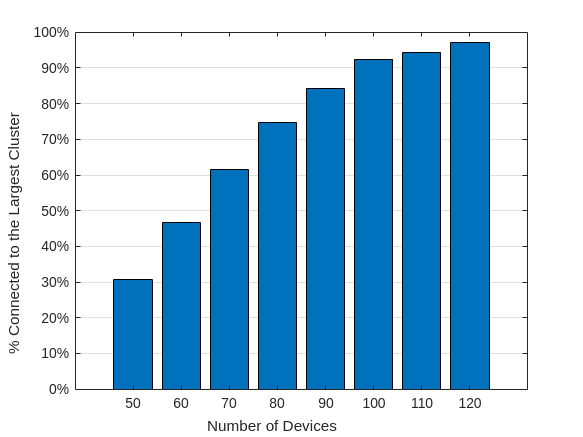

sim = Simulation(50, 300, 2000);
total = 0;
for i = 1:1000
    total = total + Simulation.simulate(50, 300, 2000, i);
end  
avg1 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(60, 300, 2000, i);
end  
avg2 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(70, 300, 2000, i);
end  
avg3 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(80, 300, 2000, i);
end  
avg4 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(90, 300, 2000, i);
    
end  
avg5 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(100, 300, 2000, i);
    
end  
avg6 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(110, 300, 2000, i);
    
end  
avg7 = total/1000*100;

total = 0;
for i = 1:1000
    total = total + Simulation.simulate(120, 300, 2000, i);
    
end  
avg8 = total/1000*100;


bar(50:10:120,[avg1,avg2,avg3,avg4,avg5,avg6,avg7,avg8]);
ytickformat('percentage')


xlabel('Number of Devices')
ylabel('% Connected to the Largest Cluster')

set(gca, "XGrid", "off", "YGrid", "on")

With 50 devices only 30% are connected to the network. With each addition of ten devices the percent connected increases before tapering off past 100 devices where we reach 93% connected. Depending on the cost of the devices it may be worth going beyond this number to reach 97% with 120 devices. Using 100 devices gives us a ratio of 25 devices per km^2.

## Section 2: CHIRP Generation

This code is meant to demonstrate the principal of the CHIRP encoding used by LoRa by implementing a very basic encoder of CHIRP signals. The signals here rise in frequency to represent a 1 and lower in frequency to represent a 0.

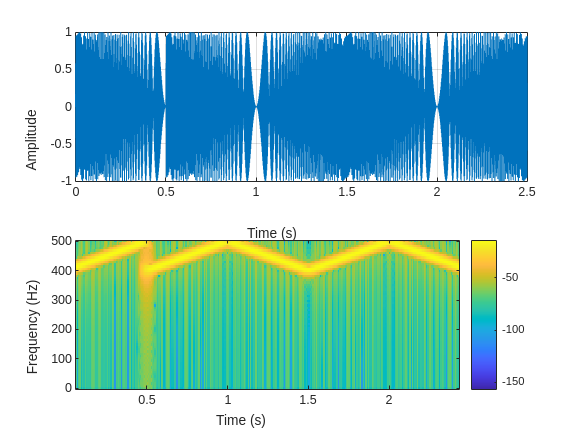

fs = 1000;          % Sampling frequency (Hz)
duration = 0.5;     % Duration of each chirp (seconds)
f0 = 400;          % Start frequency (Hz)
f1 = 500;          % End frequency (Hz)

% Create time vector for one symbol
t = 0:1/fs:duration-1/fs;
samples_per_symbol = length(t);

% Input bit sequence
bits = [1 1 0 1 0];

% Initialize output signal
chirp_signal = zeros(1, length(bits) * samples_per_symbol);

% Generate chirp for each bit
for i = 1:length(bits)
    % Calculate indices for current symbol
    idx_start = (i-1)*samples_per_symbol + 1;
    idx_end = i*samples_per_symbol;
    
    if bits(i) == 1
        % Up chirp for bit 1
        phi = 2*pi * (f0*t + (f1-f0)/(2*duration)*t.^2);
    else
        % Down chirp for bit 0
        phi = 2*pi * (f1*t + (f0-f1)/(2*duration)*t.^2);
    end
    
    chirp_signal(idx_start:idx_end) = sin(phi);
end

% Create time vector for full signal
t_full = 0:1/fs:(length(chirp_signal)-1)/fs;

% Plot the signal in time domain
figure;
subplot(2,1,1);

plot(t_full, chirp_signal);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');

% Plot the spectrogram
subplot(2,1,2);
spectrogram(chirp_signal, hamming(128), 120, 128, fs, 'yaxis');
colorbar;

Here the top graph represents the waveform of the CHIRP transmission. The graph below it represents the frequency spectrogram of the transmission. With each encoded 1 the spectrogram shows a rising frequency and each encoded 0 shows a lowering frequency. The parameters of 400hz-500hz were chosen for demonstration, a real implementation would function around 433mHz. This is not a complete implementation of the LoRa PHY layer and is just meant to demonstrate the principle of the protocol.